# **IO624 - PSI5**

The IO624 I/O module provides eight isolated automotive sensor emulator channels, which can act as PSI5 sensors. PSI5 provides asynchronous and synchronous data transmission and support including PSI5-A, PSI5-P, and PSI5-U bus topologies, and both 125 kbps and 189 kbps transmission rates.

This example demonstrates the following modes and features:

- PSI5-A (Asynchronous)

- PSI5-U/P (Synchronous without Daisy Chain) and basic bus topology

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO624 I/O module installed

- Connector cable from the I/O module to the terminal board

- 1x 50-pin terminal boards with wires

- Shunt resistor

- Oscilloscope

- ECU

### Test Setup

On the terminal board of the PSI5 sensor I/O module, connect the positive (Pin 1) channel 1 Vdd (+) to the supply line, and connect the GND (Pin 2) channel 1 Vss (GND) to ground of the supply line. 

To see how the current is modulated for the module (Transmitted Data Frame), connect the pin 2 (GND) to one terminal of the Shunt Resistor, and the opposite terminal to the ground on the Supply Line. In the oscilloscope, connect the probe input (Red) to the terminal of the shunt resistor close to the terminal board, then connect the probe ground clip (Black) to the other terminal of the resistor. See picture below.

For Synchronous mode, connect another probe input to the positive wire from the supply line, and the ground clip of the probe to the negative (GND) wire of the supply line to see the synchronous pulse from the ECU.

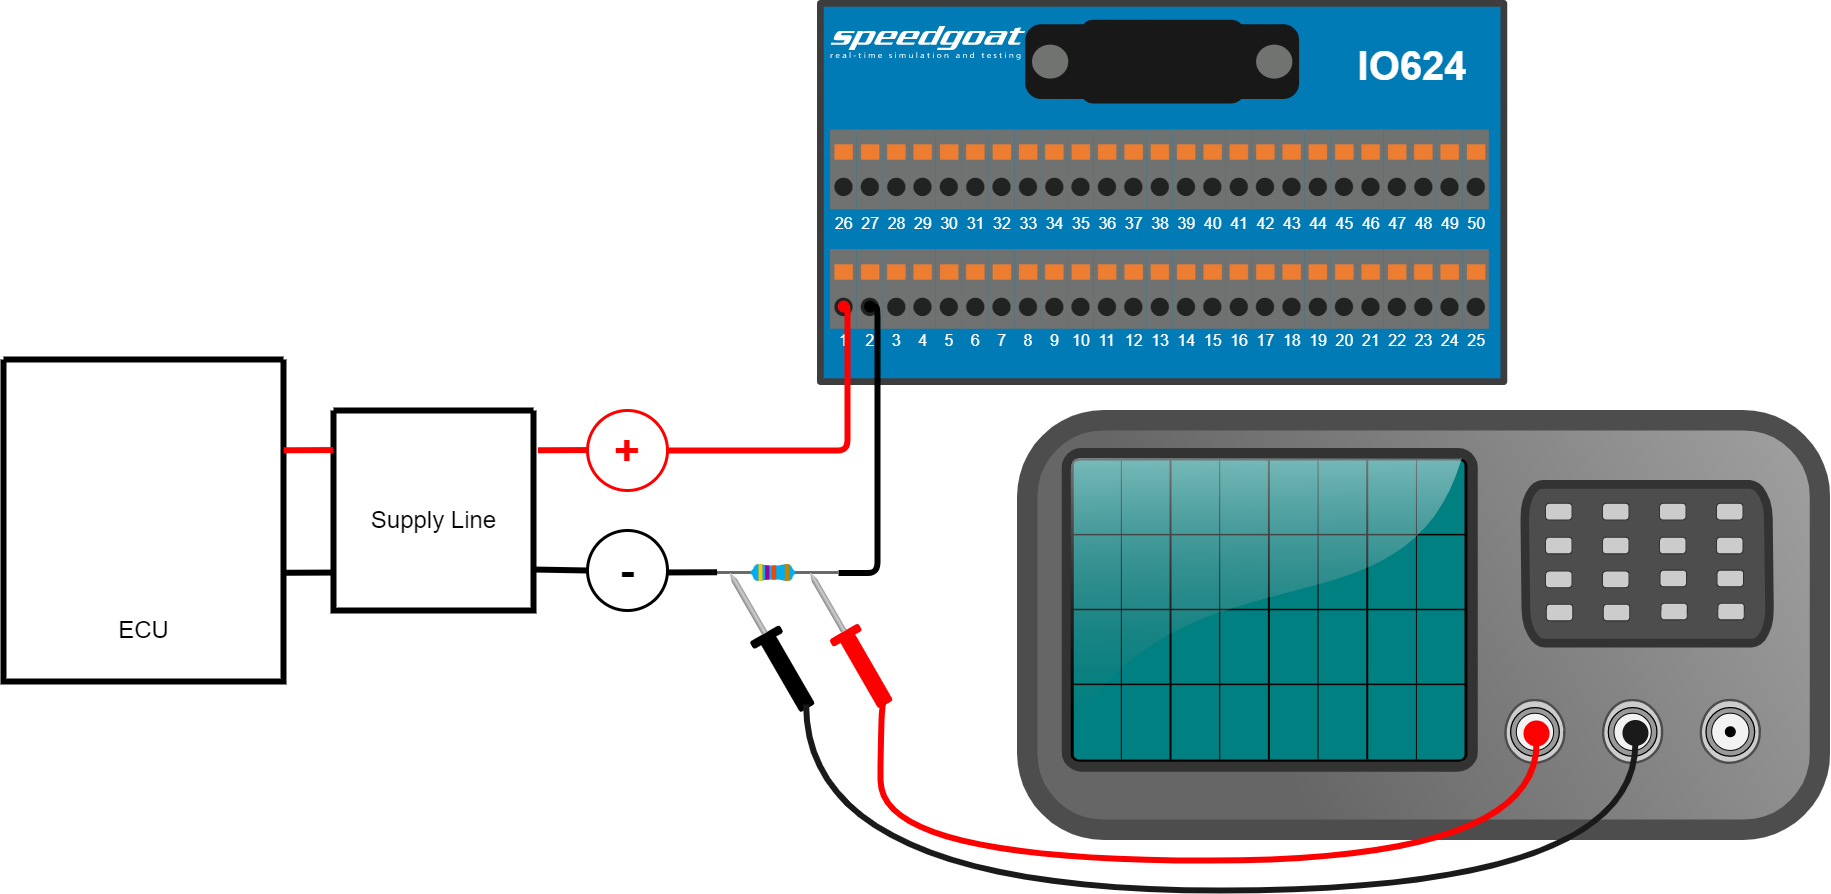

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO624_SyncAsync';
open_system(modelName);

### Model Description

The Simulink model features the [IO624 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_setup), [IO624 Sensor Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_receive), [IO624 Sensor Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_send), [IO624 Synchronous Pulses](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_sync_pulses), and [IO624 Synchronous Status](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_sync_status) blocks. All the blocks parameters are configurable in the [IO624 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_setup) block. The transmitter PSI5 frame is being generated by the [IO624 Frame](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_frame) block, that calculates automatically the CRC depending on the payload (only 7 bits in the Data Region A in this example), and outputs the payload with the CRC appended at the end.

### PSI5-A (Asynchronous)

PSI5-A describes a point-to-point connection for unidirectional, asynchronous data transmission. Each sensor is connected to the ECU by two wires. With the power supply on, after starting the model on the real-time target, the I/O module begins transmitting data to the ECU periodically, using the [IO624 Sensor Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_send) block. The **Bit Rate** and the **Cycle Time** are set in the [IO624 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_setup) block.

### PSI5-U/P (Synchronous without Daisy Chain) and basic bus topology

The synchronous operation modes work according to the **Time Division Multiple Access** (TDMA) method. Sensor data transmission is synchronized by the ECU using voltage modulation (Sync Pulses). In bus topologies, one or more sensors are connected to the ECU in parallel. Each data transmission period is initiated by a sync pulse signal from the ECU to the sensor. Having received the synchronization signal, each sensor begins transmitting its data after its corresponding **Slot Delay** (Setup block).

To support Sensor-to-ECU communication, the [IO624 Sensor Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_send) block supplies the Data Frame FIFO, which holds up to 33 data frames. To avoid data frame FIFO full error messages in the [IO624 Sync Status](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_sync_status) block, the block is placed inside a triggered subsystem. The trigger is the sync pulse signal for channel 8 (For this example the sync pulses in Ch7 and Ch8 are the same).

See [IO624 Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_usage_notes) for more information.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Results for Asynchronous mode and sync pulses

By clicking on the **Receive** scope, you should be able to see the supply voltage for asynchronous mode for channels 1 (ADC_Receive_Ch1), it variates due to the module is modulating the current.

For channels 8 (ADC_Receive_Ch8), you will see the supply voltage base 6 [v] plus sync pulses up to more than 9 [v] from the ECU.

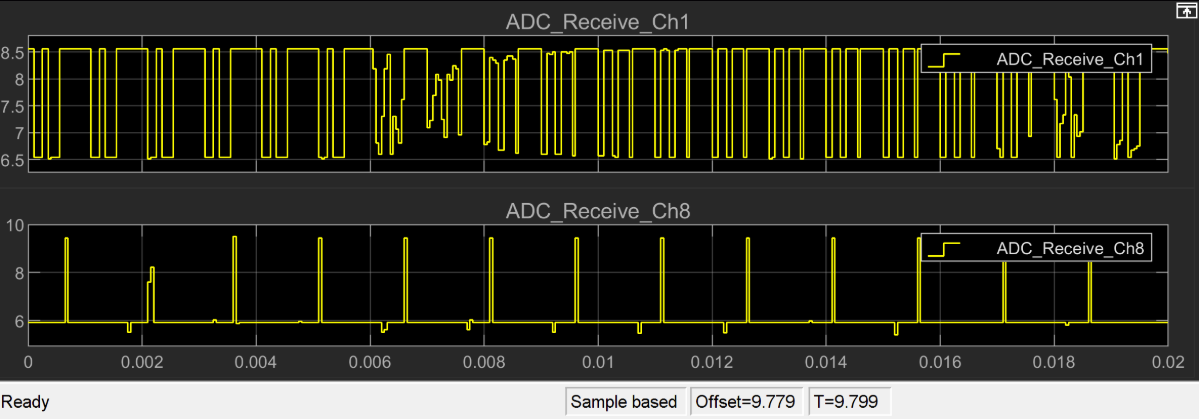

By clicking on the **Sync Pulses** scope, you should again be able to see the synchronization pulses from the ECU for channel 8. See [IO624 Synchronous Pulses](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_sync_pulses) for more information.

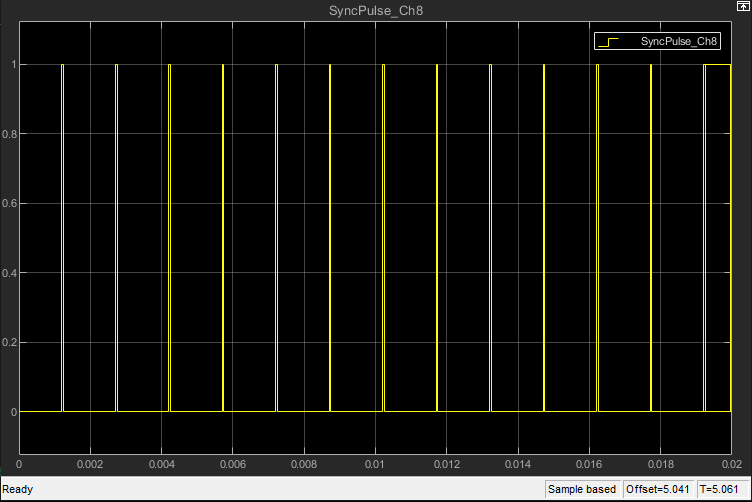

### Results for Synchronous mode by using an Oscilloscope

For this specific example, the shunt resistor is 60 [Ohm], but the max ECU total internal resistance is 12.5 [Ohm]

Once the sensor receives the sync pulse (Ch8 - Sync Pulse), each sensor begins transmitting its data after the corresponding **Slot Delay** (In the [IO624 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io624_setup) block Ch8 **Slot Delay**  645 [us]).

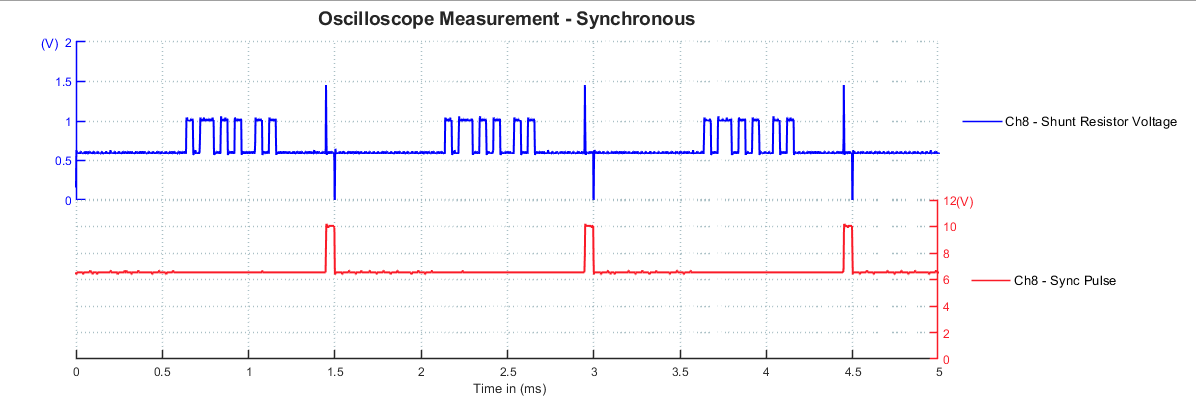

## Additional References

- [IO624 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io624)